# Prediction Model and Observation Model (EGP ver.)


$$
D_p = <(\mathbf{q}_k, \mathbf{\omega}_k, \mathrm{mApp}_k), (\Delta\hat{\mathbf{q}}_k, \Delta\hat{\mathbf{\omega}}_k)> 
= <\mathbf{x}_k, \Delta\hat{\mathbf{x}}_k> \\
D_o = <\mathbf{q}_k, \mathrm{mApp}_k>  \\
\Delta\hat{\mathbf{x}}_k = (\mathbf{x}_{k+1} - \mathbf{x}_k) - (\mathbf{x}_{k+1}' - \mathbf{x}_k')$$


予測モデルのgprの出力はモデル化誤差（形状考慮 - free motion）

csvの中身: [t_, mApp, r, v, q1, q2, q3, q4, w1, w2, w3], shape=(tspan, 15)

clc
clear
close all

curdir = pwd;
addpath(strcat(curdir, '/../../hara_functions/'));
addpath(strcat(curdir, '/../../gpryui/'));
addpath(strcat(curdir, '/../functions/'));
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得

### input values directly

shapes = ["freeMotion", "boxWing", "boxOneWing", "box"];
shapesUsed = ["freeMotion", "boxWing", "boxOneWing", "box"]; % この検証で使う形状

validScalar = [3, 3]; % どのテストデータを使うか(初期条件，形状)

tau = log(1);
sigma = log(0.25);
eta = log(0.1);
params = [tau, sigma, eta]; % hyper parameters

tstep = 1;
tspan = 0:tstep:60*3;
tstep_span = [0, tstep];

### read data

[t_, mApp, q1, q2, q3, q4, w1, w2, w3], shape=(tspan, 9)

trainDF, validDF: shape=(tspan, 9, 初期条件数, 形状数(+freeMotion))

% 事前割り当てをしたい
cddir = strcat('../../data/traindata/', shapes(1, 1), '/');
cd(cddir);
trainStruct = dir('*.csv'); % 構造体にtraindata fileを格納
fName = trainStruct(1).name; df = readmatrix(fName); % for acquiring the size of a file
trainDF = zeros(size(df, 1), size(df, 2), size(trainStruct, 1), size(shapesUsed, 2)); % 事前割り当て, shape=(tspan, 9, valid fileの数)
cd('../../../regression/EGP/');
% read train data ---------------------------------------------------------
for j = 1:1:size(shapesUsed, 2)
    cddir = strcat('../../data/traindata/', shapes(1, j), '/');
    cd(cddir);
    trainStruct = dir('*.csv'); % 構造体にtraindata fileを格納

    for i = 1:1:size(trainStruct, 1)
        fName = trainStruct(i).name;
        df = readmatrix(fName);
        trainDF(:, :, i, j) = df;
    end
    
    cd('../../../regression/EGP/');
end

cddir = strcat('../../data/validdata/', shapes(1, 1), '/');
cd(cddir);
validStruct = dir('*.csv'); % Structureにvaliddata fileを格納
fName = validStruct(1).name; df = readmatrix(fName); % for acquiring the size of a file
validDF = zeros(size(df, 1), size(df, 2), size(validStruct, 1), size(shapesUsed, 2)); % 事前割り当て, shape=(tspan, 9, valid fileの数)
cd('../../../regression/EGP/')
% read valid data ----------------------------------------------------------
for j = 1:1:size(shapesUsed, 2)
    cddir = strcat('../../data/validdata/', shapes(1, j), '/');
    cd(cddir);
    validStruct = dir('*.csv'); % Structureにvaliddata fileを格納
    
    for i = 1:1:size(validStruct, 1)
        fName = validStruct(i).name;
        df = readmatrix(fName);
        validDF(:, :, i, j) = df;
    end
   
    cd('../../../regression/EGP/')
end

### data handling

- train data (**x_y_train**: **shape**=(:, inputDim+outputDim), **input**: mApp, quaternion, and w, **output**: mApp, delta_rv_hat and delta_w_hat 学習データは全部縦に繋げる)

inputDim = 8; % [mApp, q, delta_q]
outputDim = 7;
y_shapes = zeros(size(trainDF, 1)-1, outputDim+1, size(trainDF, 3), size(trainDF, 4)); 
y_train = zeros(size(trainDF, 1)-1, outputDim, size(trainDF, 3), size(trainDF, 4)); % preallocation (出力を差分にすること考慮)
x_free = trainDF(:, 9:15, :, 1); % free motionの姿勢の時間履歴（モデル）
y_free = zeros(size(x_free, 1)-1, size(x_free, 2), size(trainDF, 3));
for k = 1:1:size(trainDF, 4)
    if k == 1
        for i = 1:1:size(trainDF, 3)
            delta_y = handleTraindata(x_free(:, :, i), trainDF(:, :, i, k)); % free motionの姿勢の時間履歴とその差分のdf
            y_free(:, :, i) = delta_y(:, 2:end); % free motionのときのmAppはいらないので，q, wの差分だけ格納
        end
    else 
        for i = 1:1:size(trainDF, 3) % fileごとに読み込んで操作
            y_shapes(:, :, i, k) = handleTraindata(x_free(:, :, i), trainDF(:, :, i, k)); % [mApp, delta_q, delta_w]
            y_shapes(isinf(y_shapes)) = NaN;
            y_shapes = fillmissing(y_shapes, 'previous'); % mAppのinfを直前の値に置換
            % モデル化誤差を計算
            y_train(:, :, i, k) = handleModelingError(y_free(:, :, i), y_shapes(:, :, i, k)); % [mApp, hat_delta_rv, hat_delta_w]
        end
    end
end
% strucrtに格納されてるデータを2次元行列に整形
x_train_mat = [];
x_y_train_mat = [];
for i = 1:1:size(x_free, 3)
    x_train_mat = [x_train_mat; x_free(1:end-1, :, i)];
end
for i = 2:1:size(y_train, 4) % freeMotionは使わないので -1
    y_train_mat = [];
    for j = 1:1:size(y_train, 3)
        y_train_mat = [y_train_mat; y_train(:, :, j, i)];
    end
    x_y_train_mat = [x_y_train_mat; [x_train_mat, y_train_mat]]; % free motionの姿勢に対する姿勢のモデル化誤差とmApp
end
% EGPのための入力行列と出力行列
x_train = [x_y_train_mat(:, inputDim), x_y_train_mat(:, 1:inputDim-1)]; % [mApp, q w]
y_train = [x_y_train_mat(:, inputDim:end)]; % [mApp, hat_delta_rv, hat_delta_w]
% train dataの各スカラー出力の平均を0にする
y_train_mean = mean(y_train); % shape=(1, outputDim)
y_train = y_train - y_train_mean; % broadcasting (y_trainの各行ベクトルについてy_train_meanを引く)


- valid data (true value)

% valid data (t_x_y_valid: (t_, mapp, quaternion, w), shape=(:,9), テストデータは繋げずに変数にそれぞれ格納
t_x_y_valid = validDF(:, :, validScalar);
t_valid = t_x_y_valid(:, 1);
t_x_y_valid(isinf(t_x_y_valid)) = NaN;
t_x_y_valid = fillmissing(t_x_y_valid, 'previous'); % mAppのinfを直前の値に置換
t_valid = t_valid(1:size(t_x_y_valid, 1), 1); 
% x_valid = [t_x_y_valid(:, 2), t_x_y_valid(:, 9:15)];
y_valid = [t_x_y_valid(:, 2), t_x_y_valid(:, 9:15)];

## 逐次的なregressionによってモデル化誤差を補完

tStart_gpr = tic;
y_reg = zeros(size(y_valid)); % shape=(:, outputDim+1), rvをqにするから列を+1
y_reg_mu = zeros(size(y_reg, 1), size(y_reg, 2)-1);
y_reg_var = zeros(size(y_reg_mu));
% x_ode = zeros()

y_reg(1,2:8) = y_valid(1,2:8); % initial condittion of q and w

### conditions for ODE

TLE = 1;
lcModel = 'AS' % Ashikhmin-Shirley model

lcModel = 'AS'

const = orbitConst; % orbitConstの構造体に軌道運動の定数が定義されてる
earthVSOP = vsopConst; % わからん．VSOP98の定数らしい

% SC model
% free motionなので形状はodeにおいて考慮しないが，たぶん必要
if validScalar(1, 2) == 2
    objName = 'boxWing.obj'
    nCompo = 3; % # of object in .obj file
    sat = readSC(objName, nCompo) % satellite shape and optical parameters
    sat.J = diag([55, 40, 65]);
    sat.m = 100;
    % optical parameters at wing (manually...)
    sat.Ca(193:end, :) = 0.1; % なんで193
    sat.Cd(193:end, :) = 0.6;
    sat.Cs(193:end, :) = 0.3;
    sat.nu = ones(size(sat.faces, 1), 1) .* 800; % とりあえずべたうち
    sat.nv = ones(size(sat.faces, 1), 1) .* 800;
    sat.F0 = ones(size(sat.faces, 1), 1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivity
elseif validScalar(1, 2) == 3
    objName = 'boxOneWing.obj'
    nCompo = 2; % # of object in .obj file
    sat = readSC("boxWing.obj", nCompo) % satellite shape and optical parameters
    % sat.J = diag([55, 40, 65]);
    sat.J = diag([40, 35, 50]);
    sat.m = 100;
    % optical parameters at wing (manually...)
    sat.Ca(193:end, :) = 0.1; % なんで193
    sat.Cd(193:end, :) = 0.6;
    sat.Cs(193:end, :) = 0.3;
    sat.nu = ones(size(sat.faces, 1), 1) .* 800; % とりあえずべたうち
    sat.nv = ones(size(sat.faces, 1), 1) .* 800;
    sat.F0 = ones(size(sat.faces, 1), 1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivity
elseif validScalar(1, 2) == 4
    objName = 'box.obj'
    nCompo = 1; % # of object in .obj file
    sat = readSC("boxWing.obj", nCompo) % satellite shape and optical parameters
    % sat.J = diag([55, 40, 65]);
    sat.J = diag([35, 35, 35]);
    sat.m = 100;
    % optical parameters at wing (manually...)
    sat.Ca(193:end, :) = 0.1; % なんで193
    sat.Cd(193:end, :) = 0.6;
    sat.Cs(193:end, :) = 0.3;
    sat.nu = ones(size(sat.faces, 1), 1) .* 800; % とりあえずべたうち
    sat.nv = ones(size(sat.faces, 1), 1) .* 800;
    sat.F0 = ones(size(sat.faces, 1), 1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivity
else
        error("invalid model flag");
end

objName = 'boxOneWing.obj'

    "Reading Object file : "    "boxWing.obj"

  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
    "Reading Material file : "    "boxWing.mtl"

  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    332     3


sat = struct with fields:
    vertices: [242×3 double]
       faces: [332×3 double]
        area: [332×1 double]
         pos: [332×3 double]
      normal: [332×3 double]
          Ca: [332×1 double]
          Cd: [332×1 double]
          Cs: [332×1 double]


% orbit
if TLE == 1
    tle = readTLE('JCSAT2.txt', const);
    tle.oe(2) = 0.0001;
else
    a = 42164.91220781728; % [km]
    e = 0.000215800000000; % eccentricity
    inc = 0.000938987137573; % [rad]
    W = 4.918899828139163; % [rad]
    w = 0.876621287411436; % [rad]
    m = 1.585708419923936; % [rad]

    tle.oe = [a e inc W w m];
    tle.jd = 2.458535992836310e+06;
end

ans =      1    69


[rIni, vIni] = oe2rv(tle.oe, 1, const); % at inertial frame, km, km/s
rIni = rIni .* 10^3; % [m]
vIni = vIni .* 10^3; % [m/s]
jd = tle.jd; % Julian day, day

% attitude
qIni = y_reg(1, 2:5);
wIni = y_reg(1, 6:8);

% arrange
xIni = [rIni, vIni, qIni, wIni];

% observer location
obsLon = deg2rad(130.216544); % longitude, [rad]
obsLat = deg2rad(33.594649); % latitude, [rad]
[obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % 球面座標から直交座標へ
obsPosECEF = obsPosECEF .* 10^3; % shape=(1, 3), [m]

qECI2ECEF = earthFullRotQ(const.J2000, tle.jd, 4, const); % (Earth attitude) quaternion from ECI to ECEF % わからん．
obsECI = qRotation(4, obsPosECEF, qInv(4, qECI2ECEF)); % observer @ECI, shape=(1, 3), [m]


### odeとgprを回して回帰モデルを構築

options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10); % 相対的な精度誤差（計算解の正しい桁数を制御），絶対許容誤差（計算解と真の解との差を制御）
[K_Dp, Kinv_Dp] = kernelMatrix(x_train, params); % x_train = [mApp, q, w]
[K_Do, Kinv_Do] = kernelMatrix(x_train(:, 2:8), params); % 観測モデルでは q, w を入力とする
x_reg = zeros(size(tspan, 2), 8); % 回帰に使う入力の初期値[mApp, q, w, hat_delta_q, hat_delta_w]
x_reg(1, :) = y_reg(1, :); % 回帰に使う入力の初期値
x_ode = zeros(size(tspan, 2), size(xIni, 2));
x_ode(1, :) = xIni;
x_shape_ode = zeros(size(tspan, 2), size(xIni, 2));
x_shape_ode(1, :) = xIni;
rv_ode_error = zeros(size(y_reg_mu, 1)-1, 3); % EGPで回帰したrvの真値
w_ode_error = zeros(size(y_reg_mu, 1)-1, 3); % EGPで回帰したwの真値

for i = 1:1:size(tspan, 2)-1

- gpr (観測ステップ)

    [y_reg_mu(i, 1), y_reg_var(i, 1)] = gprNormal(x_reg(i, 2:8), x_train(:, 2:8), y_train(:, 1), params, Kinv_Do); % input: [q_k], output: [mApp_k]
    y_reg_mu(i, 1) = y_reg_mu(i, 1) + y_train_mean(1, 1); % 回帰したmAppを平均0を戻して結果の変数に格納
    y_reg(i, 1) = y_reg_mu(i, 1);
    x_reg(i, 1) = y_reg_mu(i, 1);

- ode

    [t_, x_] = ode45(@(t, x)eomCowellFree_h(t, x, const, earthVSOP, sat, jd), tstep_span, x_ode(i, :), options);
    x_ode(i+1, :) = x_(end, :);
    q_ode = x_ode(i+1, 7:10);
    w_ode = x_ode(i+1, 11:13);

    % 形状を考慮したodeを回す（for true data of modeling error）
    [t_, x_] = ode45(@(t, x)eomCowellQ(t, x, const, earthVSOP, sat, jd), tstep_span, x_ode(i, :), options);
    x_shape_ode(i+1, :) = x_(end, :);
    q_shape_ode = x_shape_ode(i+1, 7:10);
    w_shape_ode = x_shape_ode(i+1, 11:13);
    rv_ode_error(i, :) = q2rv(qMult_h(q_shape_ode, qInv_h(q_ode)));
    w_ode_error(i, :) = w_shape_ode - w_ode;

- gpr (予測ステップ)

    for j = 2:1:size(y_reg_mu, 2)
    % 姿勢の回帰
        [y_reg_mu(i, j), y_reg_var(i, j)] = gprNormal(x_reg(i, :), x_train, y_train(:, j), params, Kinv_Dp); % 入力(:,8): mApp, q,w, 出力(:,7): mApp, hat_delta_rv, hat_delta_w
    end
    y_reg_mu(i, 2:end) = y_reg_mu(i, 2:end) + y_train_mean(1, 2:end); % 出力の平均を0にしたのを戻す
    % 回帰されたhat_delta_rvをqに戻して，姿勢計算をし，次の時刻の姿勢を求める．
    y_reg(i+1, 2:5) = qMult_h(x_ode(i+1, 7:10), rv2q(y_reg_mu(i, 2:4)));
    y_reg(i+1, 6:8) = x_ode(i+1, 11:13) + y_reg_mu(i, 5:7);
    % モデル化誤差を考慮した姿勢をodeの次の入力のために格納
    x_ode(i+1, 7:13) = y_reg(i+1, 2:8);
    % 次の回帰に使う入力を作成
    x_reg(i+1, :) = y_reg(i+1, :); % [mApp, q, w]
end

- 最後にもう一回観測ステップをやって終わり

[y_reg_mu(end, 1), y_reg_var(end, 1)] = gprNormal(y_reg(end, 2:8), x_train(:, 2:8), y_train(:, 1), params, Kinv_Do); % input: [q_k], output: [mApp_k]
y_reg_mu(end, 1) = y_reg_mu(end, 1) + y_train_mean(1, 1); % 回帰したmAppの平均0を戻す
y_reg(end, 1) = y_reg_mu(end, 1);

### export to csv

% 角速度をdegに変換
y_reg(:, 6:8) = rad2deg(y_reg(:, 6:8));
t_x_y_valid(:, 7:9) = rad2deg(t_x_y_valid(:, 7:9));
y_valid(:, 6:8) = rad2deg(y_valid(:, 6:8));

y_ode_error = [rv_ode_error, w_ode_error]; % EGPの回帰結果(rvとw)の真値
y_valid_EGP = [y_valid(1:end-1, 1), y_ode_error]; % EGPの回帰結果の真値

% y_reg_varの次元をy_regと合わせる
% y_reg_var = [y_reg_var, y_reg_var(:, end)];

savedir = strcat(curdir, '/../results/');
savename = strcat(savedir, 't_mApp_q_w_reg.csv'); writematrix([t_valid, y_reg], savename);
savename = strcat(savedir, 't_mApp_q_w_valid.csv'); writematrix(t_x_y_valid, savename);

### plot

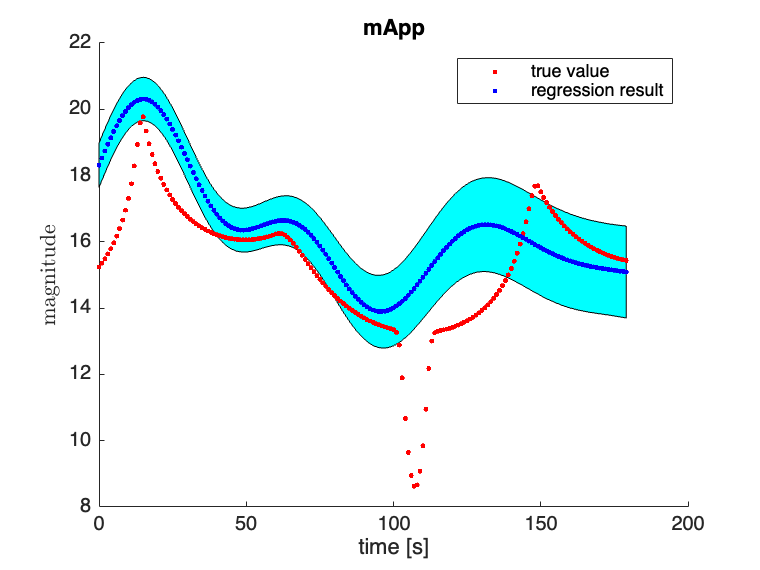

savedir = strcat(curdir, '/../results/figs/');
fignames = ["mApp", "delta_hat_rv1", "delta_hat_rv2", "delta_hat_rv3", "delta_hat_w1", "delta_hat_w2", "delta_hat_w3"];
x_label = "time [s]";
y_labels = ["magnitude", "$\Delta \hat{rv}_1$", "$\Delta \hat{rv}_2$", "$\Delta \hat{rv}_3$", "$\Delta \hat{\omega}_1$ [deg/s]", "$\Delta \hat{\omega}_2$ [deg/s]", "$\Delta\hat{\omega}_3$ [deg/s]"];

for i = 1:1:size(fignames, 2)
    figure('Name', fignames(i));
    % y_reg_muのrvとwが1つ少ない．とりあえず行を1:end-1にして対応
    plot_gpr(t_valid(1:end-1, 1), y_reg_mu(1:end-1, i), y_valid_EGP(:, i), y_reg_var(1:end-1, i), fignames(i), x_label, y_labels(i), savedir, 1);
end


% 姿勢運動をplot
fignames = ["q1", "q2", "q3", "q4", "w1", "w2", "w3"];
y_labels = ["$q1$", "$q2$", "$q3$", "$q4$", "$\omega 1$ [deg/s]", "$\omega 2$ [deg/s]", "$\omega 3$ [deg/s]"];
for i = 1:1:size(fignames, 2)
    figure('Name', fignames(i));
    plot_atti(t_valid(1:end-1, 1), y_reg(1:end-1, i+1), y_valid(1:end-1, i+1), fignames(i), x_label, y_labels(i), savedir)
end